## Separar las distintas variables de viento

wind_dir_avg = vecindario2020(vecindario2020.vars == 'Wind direction (avg.)', ["date","value"]);
wind_dir_max = vecindario2020(vecindario2020.vars == 'Wind direction (max.)', ["date","value"]);
%wind_dir_sdev = vecindario2020(vecindario2020.vars == 'Wind direction (sdev.)', ["date","value"]);
wind_speed_avg = vecindario2020(vecindario2020.vars == 'Wind speed (avg.)', ["date","value"]);
wind_speed_max = vecindario2020(vecindario2020.vars == 'Wind speed (max.)', ["date","value"]);
%wind_speed_sdev = vecindario2020(vecindario2020.vars == 'Wind speed (sdev.)', ["date","value"]);


## Hallar los valores únicos de cada tabla

[uniq_date_wda, wda_idx] = unique(wind_dir_avg.date);
[uniq_date_wdm, wdm_idx] = unique(wind_dir_max.date);

[uniq_date_wsa, wsa_idx] = unique(wind_speed_avg.date);
[uniq_date_wsm, wsm_idx] = unique(wind_speed_max.date);

## Seleccionar solo las filas con valores únicos

wind_dir_avg2 = wind_dir_avg(wda_idx, :);
wind_dir_max2 = wind_dir_max(wdm_idx, :);

wind_speed_avg2 = wind_speed_avg(wsa_idx, :);
wind_speed_max2 = wind_speed_max(wsm_idx, :);

## Juntar las variables en una sola tabla

wind_table_dir = join(wind_dir_avg2, wind_dir_max2, "Keys", "date");
wind_table_speed = join(wind_speed_avg2, wind_speed_max2, "Keys","date");

## Representar las variables

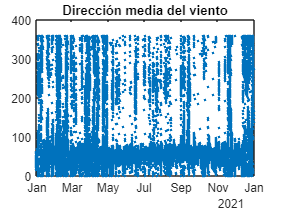

plot(wind_table_dir.date, wind_table_dir.value_wind_dir_avg2, ".")
title("Dirección media del viento")

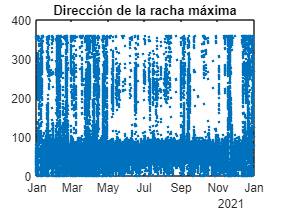

plot(wind_table_dir.date, wind_table_dir.value_wind_dir_max2, ".")
title("Dirección de la racha máxima")

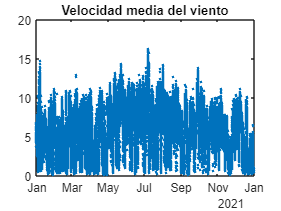


plot(wind_table_speed.date, wind_table_speed.value_wind_speed_avg2, ".")
title("Velocidad media del viento")

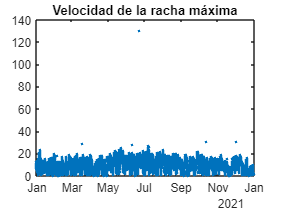

plot(wind_table_speed.date, wind_table_speed.value_wind_speed_max2, ".")
title("Velocidad de la racha máxima")

## Unir todas las variables de viento

wind_table_all = join(wind_table_speed, wind_table_dir, "Keys", "date");

## Hallar componentes de viento

[xWind, yWind] = pol2cart((pi/180).*wind_table_all.value_wind_dir_avg2, wind_table_all.value_wind_speed_avg2);

## Representar

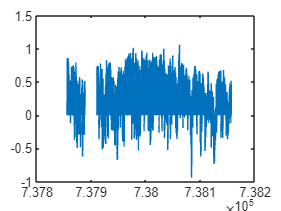

x = datenum(wind_table_all.date); 
y=x*0;
quiver(x, y, xWind, yWind)

## Encontrar fechas repetidas

% En la dirección del viento
% [C, ia,ic] = unique(wind_dir_avg.date, 'first');
% indexToDupes = find(not(ismember(1:numel(wind_dir_avg.date),ia)))
% rept = wind_dir_avg.date(indexToDupes)
% 

indexToDupes =        30285       30286       30287       30288       30289       30290


% % En la velocidad del viento 

rept = 6×1 datetime array
   25/10/2020 01:00
   25/10/2020 01:10
   25/10/2020 01:20
   25/10/2020 01:30
   25/10/2020 01:40
   25/10/2020 01:50


% [Cs, ias,ics] = unique(wind_speed_avg.date, 'first');
% indexToDupes = find(not(ismember(1:numel(wind_speed_avg.date),ias)))
% repts = wind_speed_avg.date(indexToDupes)

## Hallar media de cada día

%[wind_table_all.yr, wind_table_all.mth, wind_table_all.dy] = ymd(wind_table_all.date);

indexToDupes =        30284       30285       30286       30287       30288       30289


meanWindTable = retime(table2timetable(wind_table_all), 'daily', 'mean');

repts = 6×1 datetime array
   25/10/2020 01:00
   25/10/2020 01:10
   25/10/2020 01:20
   25/10/2020 01:30
   25/10/2020 01:40
   25/10/2020 01:50


## Representar

[xWind, yWind] = pol2cart((pi/180).*meanWindTable.value_wind_dir_avg2, meanWindTable.value_wind_speed_avg2);

x = datenum(meanWindTable.date); 
y=x*0;
quiver(x, y, xWind, yWind)